 

% 1. Generate Sample Data
numStudents = 50;
testScores = randi([50, 100], numStudents, 1); % Random scores between 50 and 100

 
meanScore = mean(testScores);
medianScore = median(testScores);
stdDevScore = std(testScores);
minScore = min(testScores);
maxScore = max(testScores);

fprintf('Mean Score: %.2f\n', meanScore);

Mean Score: 78.34


fprintf('Median Score: %.2f\n', medianScore);

Median Score: 83.00


fprintf('Standard Deviation: %.2f\n', stdDevScore);

Standard Deviation: 15.93


fprintf('Minimum Score: %d\n', minScore);

Minimum Score: 51


fprintf('Maximum Score: %d\n', maxScore);

Maximum Score: 99


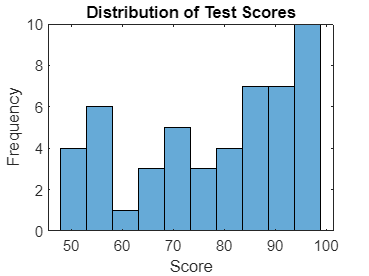


 
figure;
histogram(testScores, 10); % 10 bins
title('Distribution of Test Scores');
xlabel('Score');
ylabel('Frequency');

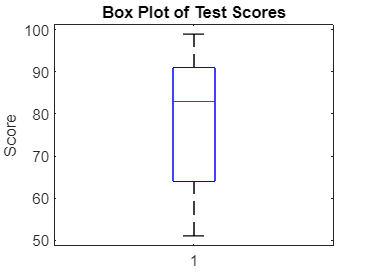


 
figure;
boxplot(testScores);
title('Box Plot of Test Scores');
ylabel('Score');


 
passingThreshold = 70;
passingStudents = sum(testScores >= passingThreshold);
failingStudents = sum(testScores < passingThreshold);

fprintf('Number of Passing Students: %d\n', passingStudents);

Number of Passing Students: 35


fprintf('Number of Failing Students: %d\n', failingStudents);

Number of Failing Students: 15


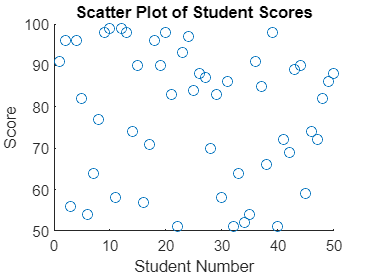


 
figure;
scatter(1:numStudents,testScores);
title('Scatter Plot of Student Scores');
xlabel('Student Number');
ylabel('Score');